# Smartfin: Mathworks Symposium

## Cal State Kalman Filter

Our test case consisted of recreating a pendulum motion with a sampling rate of 100Hz. You can see the graphs and outputs below:

clc;
clear all; %%File reading
filename = 'cleaned_data/1m_positive_fast_time.csv';
num = csvread(filename,1);
%disp(num)
time=[];  u=[];   k=[];
u1x=[];  u2x=[];  u3x=[];
u1y=[];  u2y=[];  u3y=[];
u1z=[];  u2z=[];  u3z=[];


### X - Direction

n = 972;
%disp(num(2, 2))
for i = 1:1:n
    time(i) = num(i, 2);
    %disp("time: " + num(i))
    u1x(i) = 9.8 * num(i, 3);        % x direction only
    %disp("u1: " + num(i+n))
    u2x(i) = 9.8 * num(i, 4);
    %disp("u2: " + num(i+(2*n)))
    u3x(i) = 9.8 * num(i, 5);
    %disp("u3: " + num(i+(3*n)))
end
time = time';  u1x = u1x';  u2x = u2x';  u3x = u3x';


### Y - Direction

n = 972;
%disp(num(2, 2))
for i = 1:1:n
    time(i) = num(i, 2);
    %disp("time: " + num(i))
    u1y(i) = 9.8 * num(i, 4);        % y direction only
    %disp("u1: " + num(i+n))
    u2y(i) = 9.8 * num(i, 5);
    %disp("u2: " + num(i+(2*n)))
    u3y(i) = 9.8 * num(i, 3);
    %disp("u3: " + num(i+(3*n)))
end
time = time';  u1y = u1y';  u2y = u2y';  u3y = u3y';


### Z - Direction

n = 972;
%disp(num(2, 2))
for i = 1:1:n
    time(i) = num(i, 2);
    %disp("time: " + num(i))
    u1z(i) = 9.8 * num(i, 5);        % z direction only
    %disp("u1: " + num(i+n))
    u2z(i) = 9.8 * num(i, 3);
    %disp("u2: " + num(i+(2*n)))
    u3z(i) = 9.8 * num(i, 4);
    %disp("u3: " + num(i+(3*n)))
end
time = time';  u1z = u1z';  u2z = u2z';  u3z = u3z';

## define our meta - variables

duration = size(time); %how long the simulation is
dt = 0.039;          %10 Hz continuously looking for measurement %0.039

## define update equations

A = [1 dt dt^2/2;0 1 dt;0   0 1];   %transition matrix
B = 0;
H = [1 0 0;0 1 0;0 0 1];     %genral form matrices ; measurement matrix

## define main variables

ux=0; uy = 0; uz = 0;
k1x = [u1x u2x u3x];              %control vector ; acceleration matrix
k1y = [u1y u2y u3y];              %control vector ; acceleration matrix
k1z = [u1z u2z u3z];              %control vector ; acceleration matrix
Q= [0; 0; 0];                  %initized state ; [position velocity]
Q_estimate_x = Q;
Q_estimate_y = Q;
Q_estimate_z = Q;
P = eye(3);         % q --> estimated process error covariance.
Ex = eye(3);                  %estimate of initial object position
R = [1 0 0 ;0 1 0;0 0 1];

## Initialize result variables

Z_p_x = [];    Z_v_x = [];    Z_a_x = [];
Z_p_y = [];    Z_v_y = [];    Z_a_y = [];
Z_p_z = [];    Z_v_z = [];    Z_a_z = [];


### Variables for X Direction

x_estimate_az_x = [];  y_estimate_az_x = [];  z_estimate_az_x =[];  %estimate of the object path using Kalman filter
u3_bias_x=[];   u3_perfect_x =[];
ll_x = mean(u3x);
%taking the mean of u3 will give the value and it is subtracted from
%each u3 to find bias and u3_perfect is calculated.

for t = 1:1:duration
    u3_bias_x(t) = u3x(t)-ll_x;
    u3_perfect_x(t) = u3x(t)-u3_bias_x(t);
end

### Variables for Y Direction

x_estimate_az_y = [];  y_estimate_az_y = [];  z_estimate_az_y =[];  %estimate of the object path using Kalman filter
u3_bias_y=[];   u3_perfect_y =[];
ll_y = mean(u3y);
%taking the mean of u3 will give the value and it is subtracted from
%each u3 to find bias and u3_perfect is calculated.

for t = 1:1:duration
    u3_bias_y(t) = u3y(t)-ll_y;
    u3_perfect_y(t) = u3y(t)-u3_bias_y(t);
end

### Variables for Z Direction

x_estimate_az_z = [];  y_estimate_az_z = [];  z_estimate_az_z =[];  %estimate of the object path using Kalman filter
u3_bias_z=[];   u3_perfect_z =[];
ll_z = mean(u3z);
%taking the mean of u3 will give the value and it is subtracted from
%each u3 to find bias and u3_perfect is calculated.

for t = 1:1:duration
    u3_bias_z(t) = u3z(t)-ll_z;
    u3_perfect_z(t) = u3z(t)-u3_bias_z(t);
end

## Kalman Filter for X

Q_estimate_x= [0; 0; 0];
for t = 1:1:duration
    % Predict
    % Predicted State
    Q_estimate_curr = A * Q_estimate_x + B * ux;    %-----------1
    Z_p_x = [Z_p_x; Q_estimate_curr(1)];
    Z_v_x = [Z_v_x; Q_estimate_curr(2)];
    Z_a_x = [Z_a_x; Q_estimate_curr(3)];
    %predicted next covariance
    P = A * P * A' + Ex;                         %-----------2
    % Update
    %Kalman Gain
    K = P*H'*inv(H*P*H'+R);                          %-----------3
    
    % Update the state estimate.
    y = [Q_estimate_curr(1);Q_estimate_curr(2);u3x(t)];
    Q_estimate_x = Q_estimate_curr + K * (y - H * Q_estimate_curr); %--4
    
    % update covariance estimation.
    P =  (eye(3)-K*H)*P;         %-----------5
    % Store for Plotting
    x_estimate_az_x = [x_estimate_az_x; Q_estimate_x(1)];
    y_estimate_az_x = [y_estimate_az_x; Q_estimate_x(2)];
    z_estimate_az_x = [z_estimate_az_x; Q_estimate_x(3)];
end

## Kalman Filter for Y

Q_estimate_y= [0; 0; 0];
for t = 1:1:duration
    % Predict
    % Predicted State
    Q_estimate_curr = A * Q_estimate_y + B * uy;    %-----------1
    Z_p_y = [Z_p_y; Q_estimate_curr(1)];
    Z_v_y = [Z_v_y; Q_estimate_curr(2)];
    Z_a_y = [Z_a_y; Q_estimate_curr(3)];
    %predicted next covariance
    P = A * P * A' + Ex;                         %-----------2
    % Update
    %Kalman Gain
    K = P*H'*inv(H*P*H'+R);                          %-----------3
    
    % Update the state estimate.
    y = [Q_estimate_curr(1);Q_estimate_curr(2);u3y(t)];
    Q_estimate_y = Q_estimate_curr + K * (y - H * Q_estimate_curr); %--4
    
    % update covariance estimation.
    P =  (eye(3)-K*H)*P;         %-----------5
    % Store for Plotting
    x_estimate_az_y = [x_estimate_az_y; Q_estimate_y(1)];
    y_estimate_az_y = [y_estimate_az_y; Q_estimate_y(2)];
    z_estimate_az_y = [z_estimate_az_y; Q_estimate_y(3)];
end

## Kalman Filter for Z

Q_estimate_z= [0; 0; 0];
for t = 1:1:duration
    % Predict
    % Predicted State
    Q_estimate_curr = A * Q_estimate_z + B * uz;    %-----------1
    Z_p_z = [Z_p_z; Q_estimate_curr(1)];
    Z_v_z = [Z_v_z; Q_estimate_curr(2)];
    Z_a_z = [Z_a_z; Q_estimate_curr(3)];
    %predicted next covariance
    P = A * P * A' + Ex;                         %-----------2
    % Update
    %Kalman Gain
    K = P*H'*inv(H*P*H'+R);                          %-----------3
    
    % Update the state estimate.
    y = [Q_estimate_curr(1);Q_estimate_curr(2);u3z(t)];
    Q_estimate_z = Q_estimate_curr + K * (y - H * Q_estimate_curr); %--4
    
    % update covariance estimation.
    P =  (eye(3)-K*H)*P;         %-----------5
    % Store for Plotting
    x_estimate_az_z = [x_estimate_az_z; Q_estimate_z(1)];
    y_estimate_az_z = [y_estimate_az_z; Q_estimate_z(2)];
    z_estimate_az_z = [z_estimate_az_z; Q_estimate_z(3)];
end

## Plotting for X

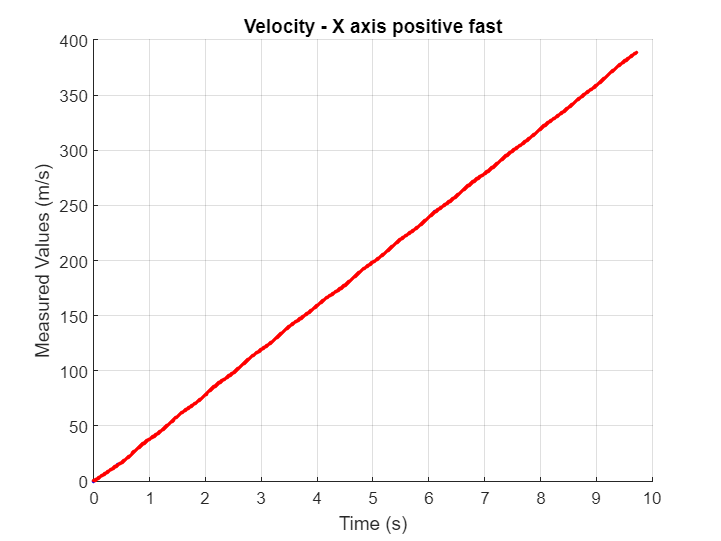

tt = 1:1:size(Z_v_x);
%x
figure;
hold on
grid on
plot(time(tt),Z_v_x,'-b.');
plot(time(tt),y_estimate_az_x,'-r.');
title('Velocity - X axis positive fast');
xlabel('Time (s)');
ylabel ('Measured Values (m/s)');
hold off

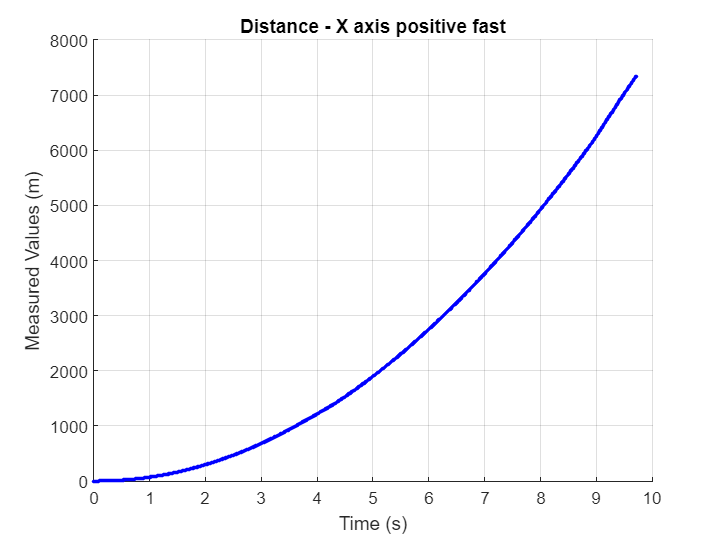


figure;
hold on
grid on
plot(time(tt),Z_p_x,'-r.');
plot(time(tt),x_estimate_az_x,'-b.');
title('Distance - X axis positive fast');
xlabel('Time (s)');
ylabel ('Measured Values (m)');
hold off

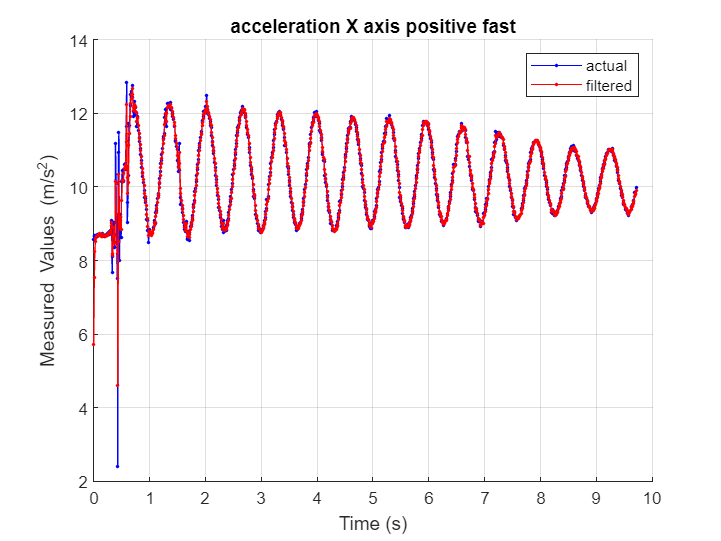


figure;
hold on
grid on
plot(time(tt),u3x(tt),'-b.');
plot(time(tt),z_estimate_az_x,'-r.');
title('acceleration X axis positive fast');
legend('actual', 'filtered')
xlabel('Time (s)');
ylabel ('Measured Values (m/s^-^2)');
hold off

## Plotting for Y

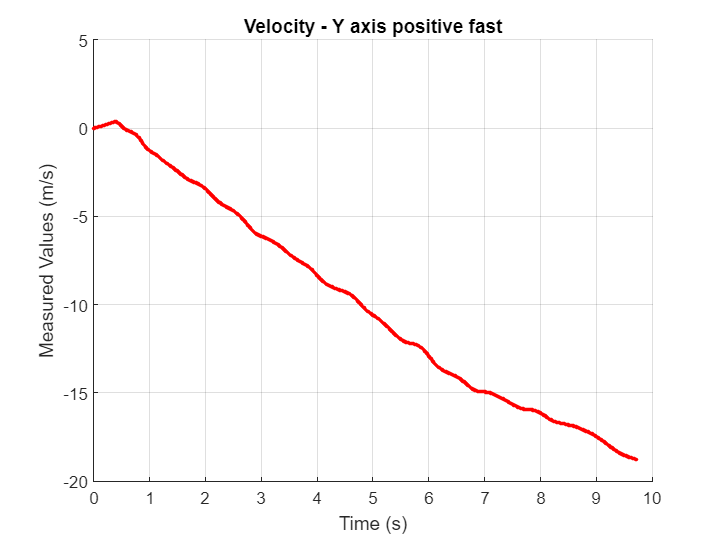

tt = 1:1:size(Z_v_y);
%x
figure;
hold on
grid on
plot(time(tt),Z_v_y,'-b.');
plot(time(tt),y_estimate_az_y,'-r.');
title('Velocity - Y axis positive fast');
xlabel('Time (s)');
ylabel ('Measured Values (m/s)');
hold off

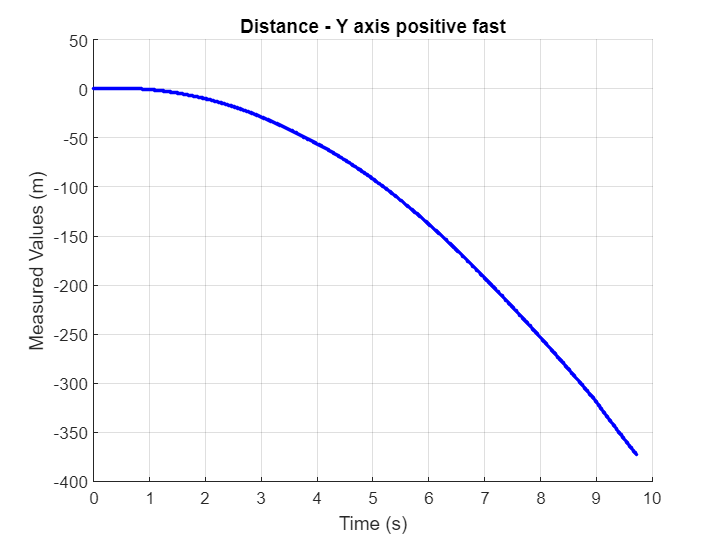


figure;
hold on
grid on
plot(time(tt),Z_p_y,'-r.');
plot(time(tt),x_estimate_az_y,'-b.');
title('Distance - Y axis positive fast');
xlabel('Time (s)');
ylabel ('Measured Values (m)');
hold off

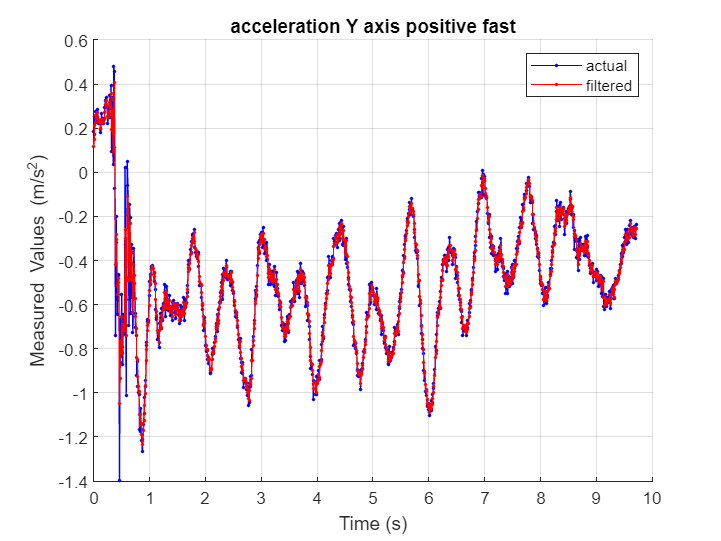


figure;
hold on
grid on
plot(time(tt),u3y(tt),'-b.');
plot(time(tt),z_estimate_az_y,'-r.');
title('acceleration Y axis positive fast');
legend('actual', 'filtered')
xlabel('Time (s)');
ylabel ('Measured Values (m/s^-^2)');
hold off

## Plotting for Z

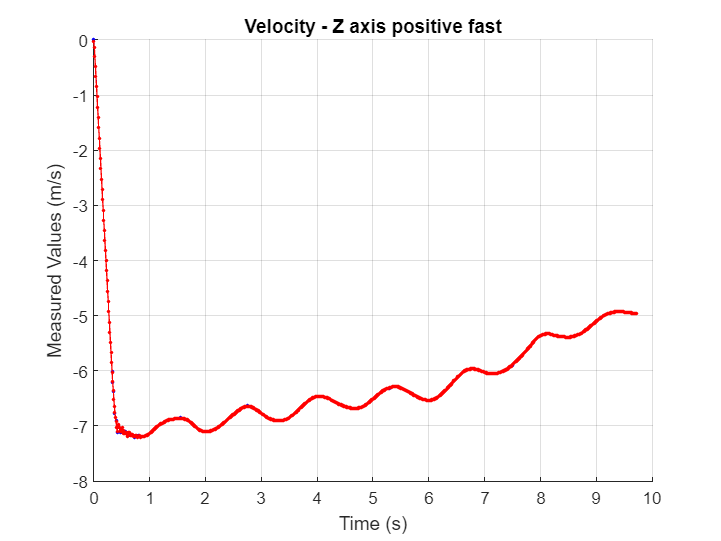

tt = 1:1:size(Z_v_z);
%x
figure;
hold on
grid on
plot(time(tt),Z_v_z,'-b.');
plot(time(tt),y_estimate_az_z,'-r.');
title('Velocity - Z axis positive fast');
xlabel('Time (s)');
ylabel ('Measured Values (m/s)');
hold off

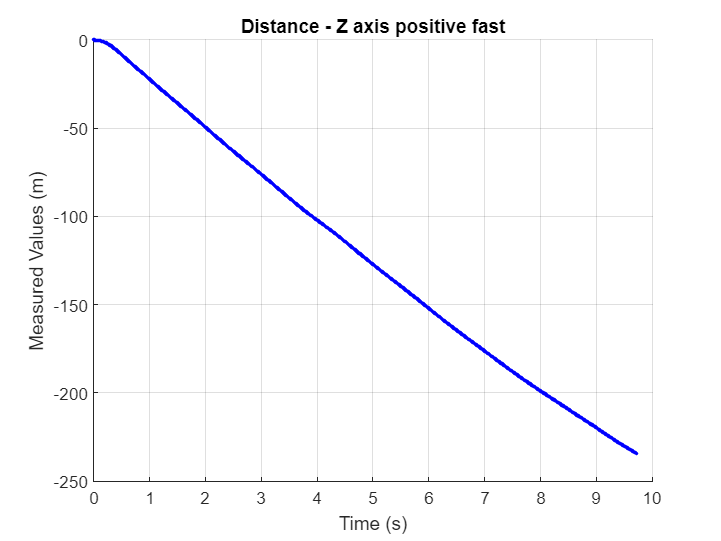


figure;
hold on
grid on
plot(time(tt),Z_p_z,'-r.');
plot(time(tt),x_estimate_az_z,'-b.');
title('Distance - Z axis positive fast');
xlabel('Time (s)');
ylabel ('Measured Values (m)');
hold off

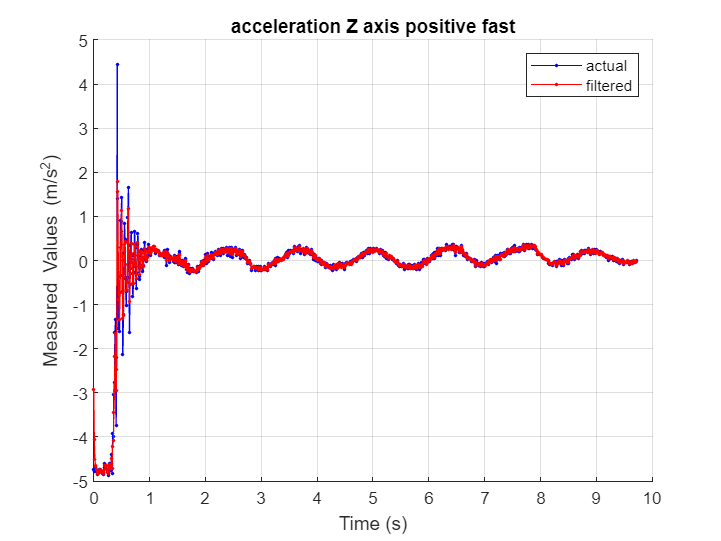


figure;
hold on
grid on
plot(time(tt),u3z(tt),'-b.');
plot(time(tt),z_estimate_az_z,'-r.');
title('acceleration Z axis positive fast');
legend('actual', 'filtered')
xlabel('Time (s)');
ylabel ('Measured Values (m/s^-^2)');
hold off

# imufilter: Estimate Orientation from IMU data

Load the IMU data which contains recorded accelerometer, gyroscope sensor data from a device oscillating in pitch (around *y*-axis), then yaw (around *z*-axis), and then roll (around *x*-axis). The sampling rate of this is 100 Hz.

filename_acc = 'cleaned_data/acc_values_vector_nav_45.csv';
filename_gyr = 'cleaned_data/gyr_values_vector_nav_45.csv';
filename_ypr = 'cleaned_data/ypr_values_vector_nav_45.csv';
filename_quat = 'cleaned_data/quat_values_vector_nav_45.csv';

Fs = 400;



acc = csvread(filename_acc,1, 1);
gyr = csvread(filename_gyr,1, 1);
ypr = csvread(filename_ypr,1, 1);
quat = csvread(filename_quat,1, 1);


accelerometerReadings = acc(1:7218,:)  ; 
%disp(accelerometerReadings);
gyroscopeReadings = gyr(1:7218, :);
%disp(gyroscopeReadings);

#### The test case we are testing here is a 45 degree rotation about the pitch or y-axis. We will plot the actual orientation values below:

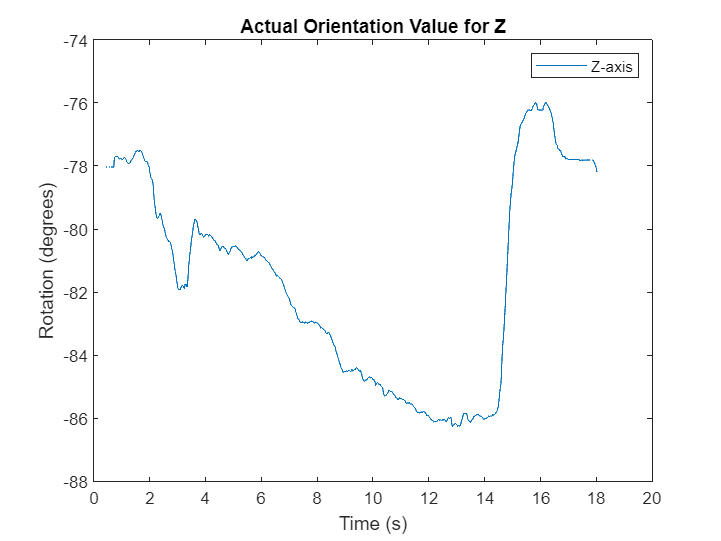

time = [1:size(ypr)]/Fs';
plot(time,ypr(:, 1))
title('Actual Orientation Value for Z')
legend('Z-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')

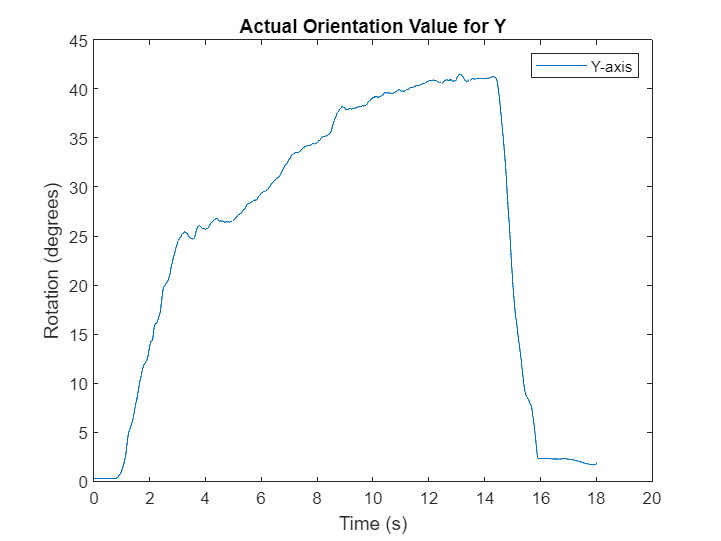

plot(time,ypr(:, 2))
title('Actual Orientation Value for Y')
legend('Y-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')

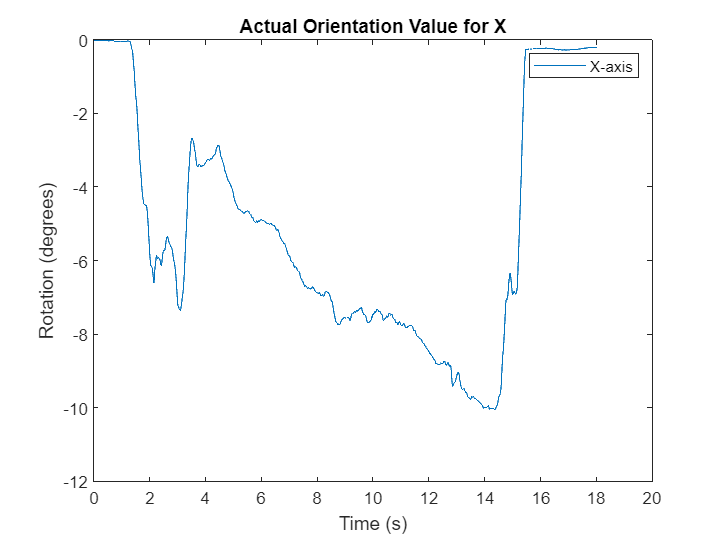

plot(time,ypr(:, 3))
title('Actual Orientation Value for X')
legend('X-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')

Create an `imufilter` System object™ with sample rate set to the sample rate of the sensor data. Specify a decimation factor of two to reduce the computational cost of the algorithm.

decim = 2;
fuse = imufilter('SampleRate',Fs,'DecimationFactor',decim);

Pass the accelerometer readings and gyroscope readings to the `imufilter` object, `fuse`, to output an estimate of the sensor body orientation over time. By default, the orientation is output as a vector of quaternions.

q = fuse(accelerometerReadings,gyroscopeReadings);

Orientation is defined by the angular displacement required to rotate a parent coordinate system to a child coordinate system. Plot the orientation in Euler angles in degrees over time.

`imufilter` fusion correctly estimates the change in orientation from an assumed north-facing initial orientation. However, the device's *x*-axis was pointing southward when recorded. To correctly estimate the orientation relative to the true initial orientation or relative to NED, use `ahrsfilter`.

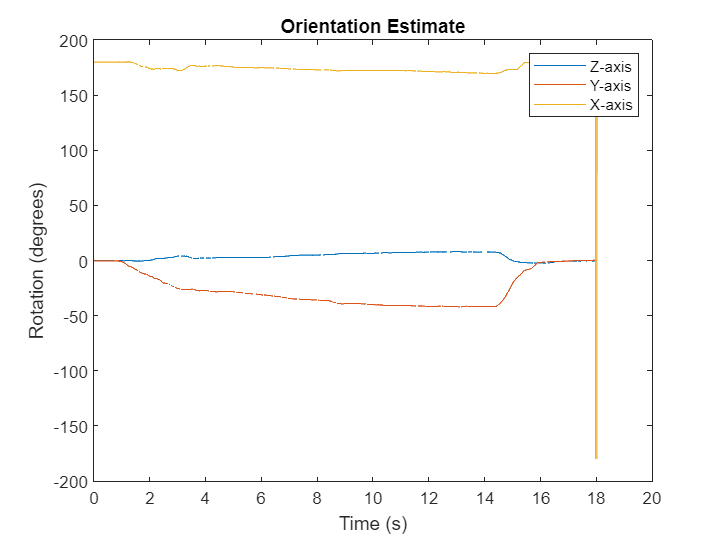

time = (0:decim:size(accelerometerReadings,1)-1)/Fs;

plot(time,eulerd(q,'ZYX','frame'))
title('Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')

m = (eulerd(q, ['ZYX'], 'frame'));
writematrix(m,'Orientation_vector_nav_results.csv') 

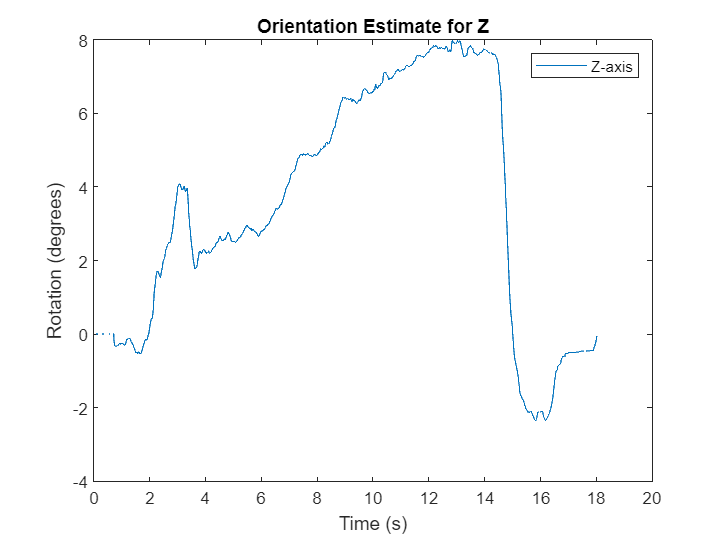

plot(time,m(:, 1))
title('Orientation Estimate for Z')
legend('Z-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')

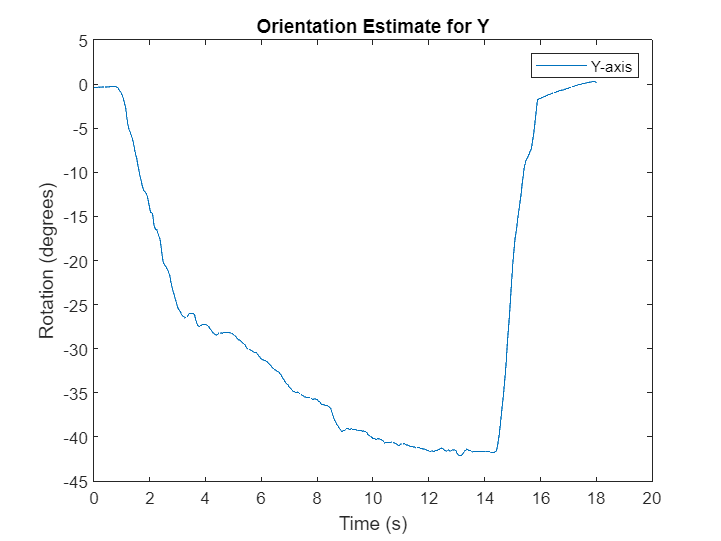

plot(time,m(:, 2))
title('Orientation Estimate for Y')
legend('Y-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')

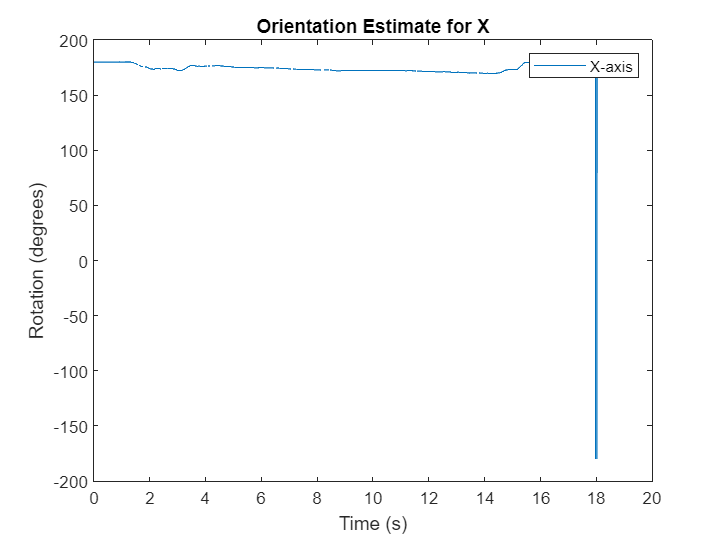

plot(time,m(:, 3))
title('Orientation Estimate for X')
legend('X-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')